# Classificació

## Netejar l'entorn

clc
close all
clear variables

## Parameters

% Scene settings
scenePath = 'imatges/DemoPratFull.png';

% Sample settings
sampleFolderPath = 'imatges/Samples/Field'; % For now using 40x40 sample images
sampleRot = 2; % Number of rotations to compute (1 - 4)

% Co-matrix settings
cmHSV = false; % If true, use saturation instead of grayscale
cmDist = 2;
cmDir = [0 1; 1 0; 1 1; -1 1];
cmSym = true; % Symmetric (offsets [1 0] == [-1 0])
cmProps = {"Contrast", "Correlation", "Energy", "Homogeneity"};

% Sliding Window settings
swStep = 10;

% Classification settings
nbest = 0; % Show best nbest cases. If 0, show cases better than threshold.
thr = 0.75;

% Presentation settings
maskAlpha = 0.65;

## Load sample filepaths

sampleImds = imageDatastore(sampleFolderPath, IncludeSubfolders = true, LabelSource = "foldernames");

sampleFiles = size(sampleImds.Files, 1);
sampleCases = sampleFiles*sampleRot;

## Processem la mostra

sampleProps = NaN(size(cmProps, 2), size(cmDir, 1), sampleCases);
for sf = 1:sampleFiles

    sampleImg = readimage(sampleImds, sf);

    if cmHSV == false
        sampleImg2 = im2gray(sampleImg);
    else
        sampleImg2 = rgb2hsv(sampleImg);
        sampleImg2 = sampleImg2(:,:,1); % Hue
    end

    for rot = 1:sampleRot
    
        sampleImg2Rot = rot90(sampleImg2, rot-1);
        sampleProps(:, :, (sf-1)*sampleRot+rot) = extractFeaturesGLCM(sampleImg2Rot, cmDir*cmDist, cmSym, cmProps);
    
    end
end

## Propietats de la mostra

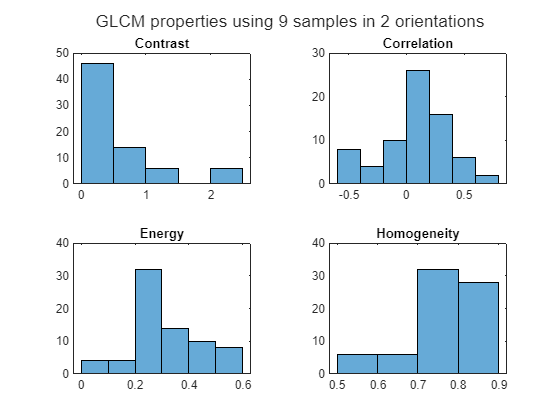

figure,
tiledlayout('flow'), sgtitle(sprintf('GLCM properties using %i samples in %i orientations', sampleFiles, sampleRot));
for sp = 1:size(cmProps, 2)
    nexttile,
    histogram(sampleProps(sp,:,:)), title(cmProps{1,sp});
end

## Processem l'escena

sceneImg = imread(scenePath);

if cmHSV == false
    sceneImg2 = im2gray(sceneImg);
else
    sceneImg2 = rgb2hsv(sceneImg);
    sceneImg2 = sceneImg2(:,:,1); % Hue
end

## Busquem coincidencies

swSize = size(sampleImg2); % Sliding window must match sample size
sceneSize = size(sceneImg2);

swNumY = floor( (sceneSize(1)-swSize(1)) / swStep );
swOffsetsY = swStep*(1:swNumY);

swNumX = floor( (sceneSize(2)-swSize(2)) / swStep );
swOffsetsX = swStep*(1:swNumX);

%tic
err = NaN(swNumY, swNumX, sampleCases);
parfor ny = 1:swNumY
    for nx = 1:swNumX

        y = swOffsetsY(ny);
        x = swOffsetsX(nx);

        swSample = sceneImg2(y:(y+swSize(1)-1), x:(x+swSize(2)-1));
        swProps = extractFeaturesGLCM(swSample, cmDir*cmDist, cmSym, cmProps);

        for sc = 1:sampleCases
            err(ny, nx, sc) = sum( abs(sampleProps(:,:,sc) - swProps), 'all');
        end

    end
end
%toc

## Find matching cases

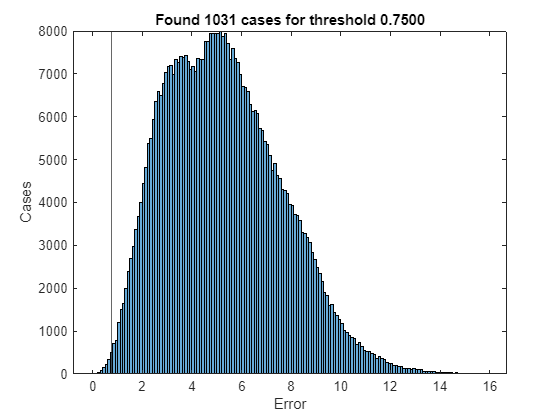

if nbest ~= 0
    bestThr = sort(err(:));
    thr = bestThr(nbest);
end

figure,
histogram(err(:,:,:)), xline(thr), xlabel('Error'), ylabel('Cases'),
title(sprintf('Found %i cases for threshold %.4f', sum(err(:) <= thr), thr));

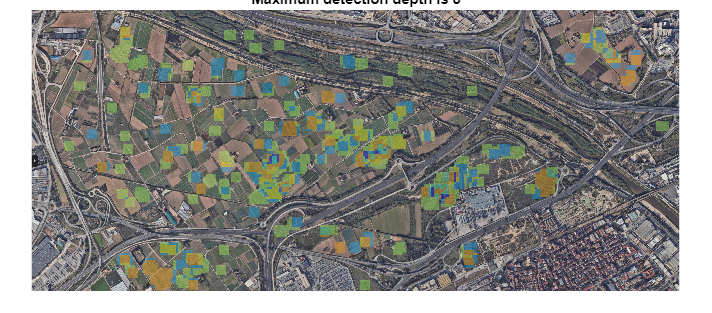


%tic
mask = false(sceneSize(1), sceneSize(2), sampleCases);
for ny = 1:swNumY
    for nx = 1:swNumX
        for sc = 1:sampleCases
            if err(ny, nx, sc) <= thr
    
                y = swOffsetsY(ny);
                x = swOffsetsX(nx);
    
                mask(y:(y+swSize(1)-1), x:(x+swSize(2)-1), sc) = 1;
    
            end
        end
    end
end
%toc

mask = sum(mask,3);
figure,
imshow( labeloverlay(sceneImg, mask, Transparency = maskAlpha)), title(sprintf('Maximum detection depth is %i', max(mask(:))));